# Spherical Coordinates and Rotations

In this demo, we will illustrate some basic MATLAB tools for computing and displaying antenna patterns. Specifically, you will learn to:

- Perform basic manipulations in spherical coordinates

- Create a rotation matrix with Euler angles

## Spherical Coordiantes

We first demonstrate how to perform basic manipulations in spherical coordinates. 

For example, the code below generates `nx` random points in 3D and converts them to spherical coordinates

% Generate random data
nx = 4;
d = 3;  
X = randn(nx,d);

% Compute spherical coordinates of a matrix of points
% Note these are in radians!
[az, el, rad] = cart2sph(X(:,1), X(:,2), X(:,3));

% We can then convert back
[x,y,z] = sph2cart(az,el,rad);
Xhat = [x y z];

% You should see they are equal:
disp(X);

   -1.0642   -1.5062   -0.2612
    1.6035   -0.4446    0.4434
    1.2347   -0.1559    0.3919
   -0.2296    0.2761   -1.2507



disp(Xhat);

   -1.0642   -1.5062   -0.2612
    1.6035   -0.4446    0.4434
    1.2347   -0.1559    0.3919
   -0.2296    0.2761   -1.2507



## Euler Anlges and Rotation matrices

The following code shows how to create rotations with the Euler angles yaw, pitch and roll.  We also see the effect of rotations

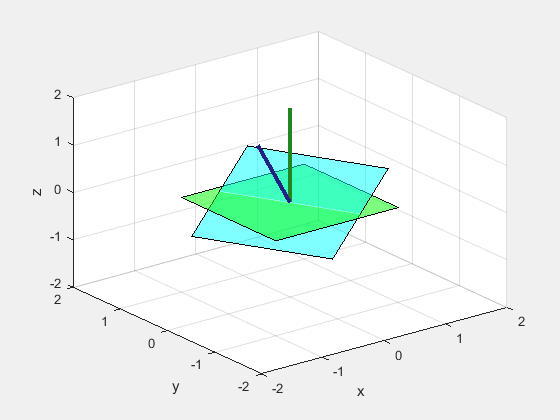


% Vertices and facets for a plane
vert = [-1 -1 0; 1 -1 0; 1 1 0; -1 1 0];
fac = [1 2 3 4];
nvec = [0 0 2];  % normal vector


clf;

% Set the axes 
xlim([-2, 2]);
ylim([-2, 2]);
zlim([-2, 2]);
grid on;
view(120,30);
xlabel('x');
ylabel('y');
zlabel('z');

% Draw the original plane
cline = [34 134 34]/256;
patch('Vertices', vert, 'Faces', fac, 'FaceColor', 'green', 'FaceAlpha', 0.5);
hold on;
plot3([0 nvec(1)], [0 nvec(2)], [0 nvec(3)], 'Linewidth', 3, 'Color', cline);


% Set the rotation angles
yaw =28;
pitch =-30;
roll =0;

% Create the rotation matrix
R = eul2rotm(deg2rad([yaw pitch roll]), 'ZYX');

vertRot = vert*R';  % Rotate the vertices
nvecRot = nvec*R';  % Rotate the normal vector

% Plot the rotated plane
cline = [34 34 134]/256;
patch('Vertices', vertRot, 'Faces', fac, 'FaceColor', 'cyan', 'FaceAlpha', 0.5);
plot3([0 nvecRot(1)], [0 nvecRot(2)], [0 nvecRot(3)], 'Linewidth', 3, 'Color', cline);
view(3);
hold off;